**The validation of our theory with experimental data.**

**For Figure 4 ab and Figure S2.**

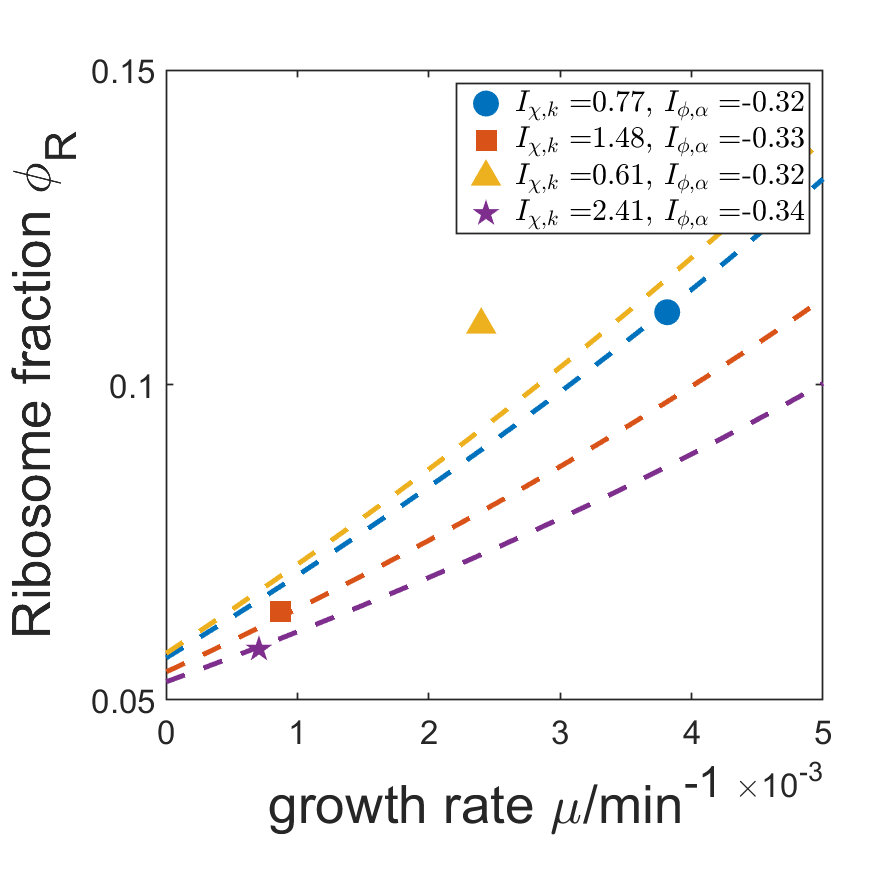

%%%initialization
rng('shuffle');
total=2e3;
muphi=zeros(total,6);

colors=["#0072BD" 
        "#D95319" 
        "#EDB120" 
        "#7E2F8E"
        "#77AC30" 
        "#4DBEEE" 
        "#A2142F" 
        '#FF0000' 
        '#00FF00' 
        '#0000FF' 
        '#00FFFF' 
        '#FF00FF' 
        '#FFFF00' 
        '#000000' 
        '#FFFFFF'];
markers=["o" 
        "s" 
        "^" 
        "p"
        "h" 
        "v" 
        "<" 
        '>'];

N=4e3;

CV_keff=1.97;
mean_keff=48000;%Da/min
sigmay=sqrt(log(1+CV_keff^2));
meany=log(mean_keff)-sigmay^2/2;
keff=exp(meany+sigmay*randn(N,1));
keff_R=20700;



CV_alpha=1.755436;
mean_alpha=1.1e-3;%min-1
sigmay=sqrt(log(1+CV_alpha^2));
meany=log(mean_alpha)-sigmay^2/2;
alpha_oth=exp(meany+sigmay*randn(N-1,1));
alphaR=4.83e-4;
alpha=[alphaR;alpha_oth];

phi0=0.048;
chiRmax=1;
dphi=1e-3;

var_chi=zeros(1,total);


%import the experimental data
exp_data=[readmatrix("../Data_analysis/sum_data_Friedrich2021.csv")];

%exp_data=[readmatrix("../../critical_art/rana/sum_data_Friedrich2021_nocalib.csv")];
%The experimental data without calibration of phi for Figure S2b

%exp_data=[readmatrix("../../critical_art/rana/sum_data_Friedrich2021_Lcalib.csv")];
%The experimental data in which phi is calibrated with L−1 for Figure S2c


mu_exp=exp_data(:,6)';
phR_exp=exp_data(:,5)';
Ikx=exp_data(:,2)';
Ialpx=exp_data(:,3)';
mR_exp=exp_data(:,4)';



fig=figure;
set(fig,'Position',[300 100 700 700]);

ax1=axes('position', [0.19 0.2 0.75 0.72]);


for i_0=1:(length(Ikx)-0)

%prediction
muphi_pre=IkxIak_sol_fun(total, ...
    Ikx(i_0), ...
    Ialpx(i_0), ...
    mean_keff, ...
    keff_R, ...
    mean_alpha, ...
    alphaR, ...
    phi0, ...
    mR_exp(i_0));

%muphi_pre=IkxIak_sol_fun(total, ...
%    Ikx(i_0), ...
%    Ialpx(i_0), ...
%    mean_keff, ...
%    keff_R, ...
%    mean_alpha, ...
%    alphaR, ...
%    0.048, ...
%    1.4e6);
%actual ribosomal mass mR = 1.40 × 106 Da is used for Figure S2a

%plot the predictions
plot(muphi_pre(:,1),muphi_pre(:,2),'--', ...
    "Color",colors(i_0), ...
    "LineWidth",3) ;

hold on

end

%plot the experimental data
for i = 1:length(mu_exp)
    p(i)=plot(mu_exp(i),phR_exp(i),'o', ...
    "MarkerFaceColor",colors(i), ...
    'DisplayName', ['$I_{\chi,k} = $',num2str(Ikx(i),'%.2f'),', $I_{\phi,\alpha} = $',num2str(Ialpx(i),'%.2f')] , ...
    "MarkerSize",15,...
    "Color",colors(i), ...
    "Marker",markers(i));
hold on;
end
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p(1:4)],"Interpreter","latex")
xlabel('growth rate \mu/min^{-1}','interpreter','tex','FontSize',32);
ylabel('Ribosome fraction \phi_R','interpreter','tex','FontSize',32);
axis([0,0.005,0.05,0.15]);
hold off

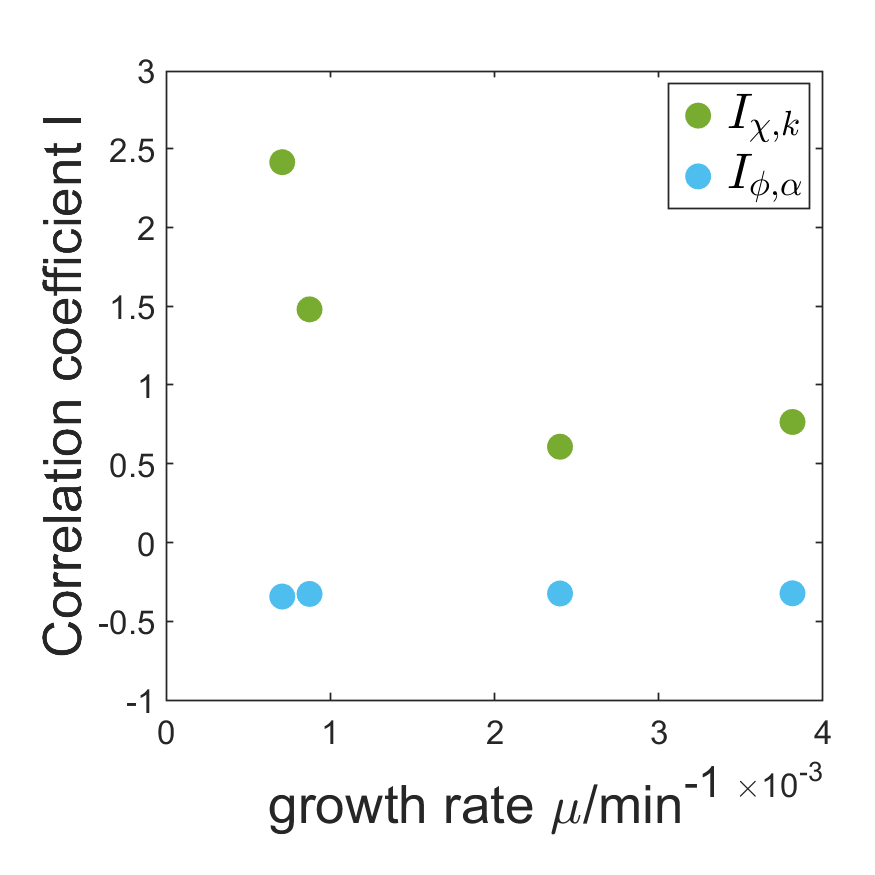



fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);


%plot the distribution of Ikx and Iphia
p1=plot(mu_exp,Ikx,'o', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",colors(5),...
    "MarkerFaceColor",colors(5), ...
    "DisplayName","$I_{\chi,k}$");
hold on
p2=plot(mu_exp,Ialpx,'o', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",colors(6),...
    "MarkerFaceColor",colors(6), ...
    "DisplayName","$I_{\phi,\alpha}$");
ylim([-1,3]);
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2],"Interpreter","latex","FontSize",30)
xlabel('growth rate \mu/min^{-1}','interpreter','tex','FontSize',32);
ylabel('Correlation coefficient I','interpreter','tex','FontSize',32);

The prediction function.

function[muphi]=IkxIak_sol_fun(total,Ikx,Ialpx,mean_keff,kR,mean_alpha,alphaR,phi0,mR)
  
muphi=zeros(total,6);



   chiR=0:1/(total-1):1;
   phiR=(mR*mean_alpha + mean_keff*phi0 + Ialpx*mR*mean_alpha + Ikx*mean_keff*phi0 + chiR*kR*phi0 - chiR*mean_keff*phi0 - Ikx*chiR*mean_keff*phi0)./(mean_keff + Ikx*mean_keff + chiR*kR - alphaR*mR - chiR*mean_keff + mR*mean_alpha - Ikx*chiR*mean_keff + Ialpx*mR*mean_alpha) - (alphaR*mR - chiR*kR + mR*mean_alpha + mean_keff*phi0 - sqrt(Ialpx^2*mR^2*mean_alpha^2 - 2*Ialpx*Ikx*chiR*mR*mean_keff*mean_alpha*phi0 + 2*Ialpx*Ikx*mR*mean_keff*mean_alpha*phi0 - 2*Ialpx*alphaR*mR^2*mean_alpha - 2*Ialpx*chiR*kR*mR*mean_alpha*phi0 + 2*Ialpx*chiR*kR*mR*mean_alpha - 2*Ialpx*chiR*mR*mean_keff*mean_alpha*phi0 + 2*Ialpx*mR^2*mean_alpha^2 + 2*Ialpx*mR*mean_keff*mean_alpha*phi0 + Ikx^2*chiR.^2*mean_keff^2*phi0^2 - 2*Ikx^2*chiR*mean_keff^2*phi0^2 + Ikx^2*mean_keff^2*phi0^2 + 2*Ikx*alphaR*chiR*mR*mean_keff*phi0 - 2*Ikx*alphaR*mR*mean_keff*phi0 - 2*Ikx*chiR.^2*kR*mean_keff*phi0^2 + 2*Ikx*chiR.^2*kR*mean_keff*phi0 + 2*Ikx*chiR.^2*mean_keff^2*phi0^2 + 2*Ikx*chiR*kR*mean_keff*phi0^2 - 2*Ikx*chiR*kR*mean_keff*phi0 - 2*Ikx*chiR*mR*mean_keff*mean_alpha*phi0 - 4*Ikx*chiR*mean_keff^2*phi0^2 + 2*Ikx*mR*mean_keff*mean_alpha*phi0 + 2*Ikx*mean_keff^2*phi0^2 + alphaR^2*mR^2 + 2*alphaR*chiR*kR*mR*phi0 - 2*alphaR*chiR*kR*mR + 2*alphaR*chiR*mR*mean_keff*phi0 - 2*alphaR*mR^2*mean_alpha - 2*alphaR*mR*mean_keff*phi0 + chiR.^2*kR^2*phi0^2 - 2*chiR.^2*kR^2*phi0 + chiR.^2*kR^2 - 2*chiR.^2*kR*mean_keff*phi0^2 + 2*chiR.^2*kR*mean_keff*phi0 + chiR.^2*mean_keff^2*phi0^2 - 2*chiR*kR*mR*mean_alpha*phi0 + 2*chiR*kR*mR*mean_alpha + 2*chiR*kR*mean_keff*phi0^2 - 2*chiR*kR*mean_keff*phi0 - 2*chiR*mR*mean_keff*mean_alpha*phi0 - 2*chiR*mean_keff^2*phi0^2 + mR^2*mean_alpha^2 + 2*mR*mean_keff*mean_alpha*phi0 + mean_keff^2*phi0^2) + Ialpx*mR*mean_alpha + Ikx*mean_keff*phi0 + chiR*kR*phi0 - chiR*mean_keff*phi0 - Ikx*chiR*mean_keff*phi0)./(2*(mean_keff + Ikx*mean_keff + chiR*kR - alphaR*mR - chiR*mean_keff + mR*mean_alpha - Ikx*chiR*mean_keff + Ialpx*mR*mean_alpha));
   mu= - alphaR - (chiR.*kR.*(phi0./phiR - 1))/mR;
   
 
   temp1(1:total)=Ikx;
   temp2(1:total)=Ialpx;
   muphi=[mu;phiR;temp1;temp2;chiR;zeros(1,total)];
   muphi=muphi';
    


pp=find(muphi(:,1)<0);
muphi(pp,:)=[];
pp=find(muphi(:,2)<0);
muphi(pp,:)=[];
pp=find(muphi(:,2)>1);
muphi(pp,:)=[];


end

